# Representational Similarity Analysis tutorial

Author: Choong-Wan Woo (Sungkyunkwan University) [https://cocoanlab.github.io/](https://cocoanlab.github.io/)

## Dataset

- from Woo et al., 2014, Nat Comms (download: [https://cocoanlab.github.io/pdfs/Woo_2014_NatComms.pdf](https://cocoanlab.github.io/pdfs/Woo_2014_NatComms.pdf))

- N = 59

- There were two types of tasks, and in each task, there were two conditions (2 x 2 design)

- -- Physical pain task (Heat, Warmth conditions)

- -- Social pain task (Rejection, Friends conditions)

## Analysis plan

- Computing RDMs for each participant, for each region (4 ROIs: aINS, dACC, S2/dpINS, TPJ and 1 whole-brain mask), and visualize the average RDMs (the whole-brain mask was created using neurosynth [10/04/2013] with the a priori terms, 'pain', 'emotion', and 'social'; the union of forward and reverse inference maps at q < .1, FDR corrected)

- Comparing brain (4 ROIs and whole-brain masks) and model RDMs -- We will use four model RDMs to test: heat vs. others (HO), rejection vs. others (RO), physical vs. social (PS), aversive vs. non-aversive (AN)

- Statistical inference: Using each brian mask, we will do statistical inference for four models above

## Key research question:

        Which one is the best-supported model based on the representational similarity patterns from our empirical data? 

## Step 1: Computing and visualizing RDMs

Here, I will compute the representational dissimilarity matrices for 4 ROIs and also the whole-brain mask and visualize them. 

### Basic setup

clear all;
% directory setup
basedir = '/Users/clinpsywoo/Dropbox/github/RSA_tutorial/tutorial';
% you need to change the first part of the path into your path directories

datdir = fullfile(basedir, 'data', 'contrast_images');

roi_masks = filenames(fullfile(basedir, 'masks', '*smooth_mirror.nii'));
roi_masks{5} = filenames(fullfile(basedir, 'masks', '*Woo2014.nii'), 'char');
% filenames is a useful function from CanlabCore toolbox

conditions = {'heat', 'warmth', 'rejection', 'friend'};

line_disp = repmat('=', 1, 50); % for display

addpath(fullfile(basedir, 'external'));


### Reading data for ROI masks

for i = 1:numel(roi_masks)
    [~, roi{i}.name] = fileparts(roi_masks{i});
    disp(line_disp);
    fprintf('Reading data from %s\n', roi{i}.name);
    disp(line_disp);
    roi{i}.heat = fmri_data(filenames(fullfile(datdir, 'heat_sub_*.nii')), ...
        roi_masks{i});
    roi{i}.warmth = fmri_data(filenames(fullfile(datdir, 'warmth_sub_*.nii')), ...
        roi_masks{i});
    roi{i}.rejection = fmri_data(filenames(fullfile(datdir, 'rejection_sub_*.nii')), ...
        roi_masks{i});
    roi{i}.friend = fmri_data(filenames(fullfile(datdir, 'friend_sub_*.nii')), ...
        roi_masks{i});
end

Reading data from S2_dpINS_smooth_mirror


Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.590134초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.435834초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.462863초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 1475472 bytes
Loading image number:    59
경과 시간은 0.453578초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from aINS_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.383526초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.401936초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.340806초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 691008 bytes
Loading image number:    59
경과 시간은 0.372575초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from dACC_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.316202초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.297276초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.281323초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 434476 bytes
Loading image number:    59
경과 시간은 0.271388초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from tpj_smooth_mirror


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.297972초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.218352초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.212754초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 330872 bytes
Loading image number:    59
경과 시간은 0.272862초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


Reading data from neurosynth_mask_Woo2014


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.913784초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.889736초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 0.902892초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 15975312 bytes
Loading image number:    59
경과 시간은 1.551369초입니다.
Image names entered, but fullpath attribute is empty. Getting path info.


### Computing RDMs for each region and for each individual

n_subj = size(roi{1}.heat.dat,2);

for roi_i = 1:numel(roi)
    if roi_i == 1, disp(line_disp); fprintf('Computing RDMs for ROIs...\n'); end
    roi{roi_i}.rdms = zeros(4,4);
    for cond_i = 1:numel(conditions)
        for cond_j = 1:numel(conditions)
            if cond_i ~= cond_j
                for subj_i = 1:n_subj

                    eval(['roi{roi_i}.rdms(cond_i,cond_j,subj_i) = 1-corr(roi{roi_i}.' ...
                        conditions{cond_i} '.dat(:,subj_i), roi{roi_i}.' ...
                        conditions{cond_j} '.dat(:,subj_i));']);
                    
                    roi{roi_i}.rdms(cond_j,cond_i,subj_i) = ...
                        roi{roi_i}.rdms(cond_i,cond_j,subj_i); % to make RDMs symmetric
                    
                end
            end
        end
    end
    if roi_i == numel(roi), fprintf('DONE.\n'); disp(line_disp); end
end

Computing RDMs for ROIs...


DONE.


### Visualize mean RDMs

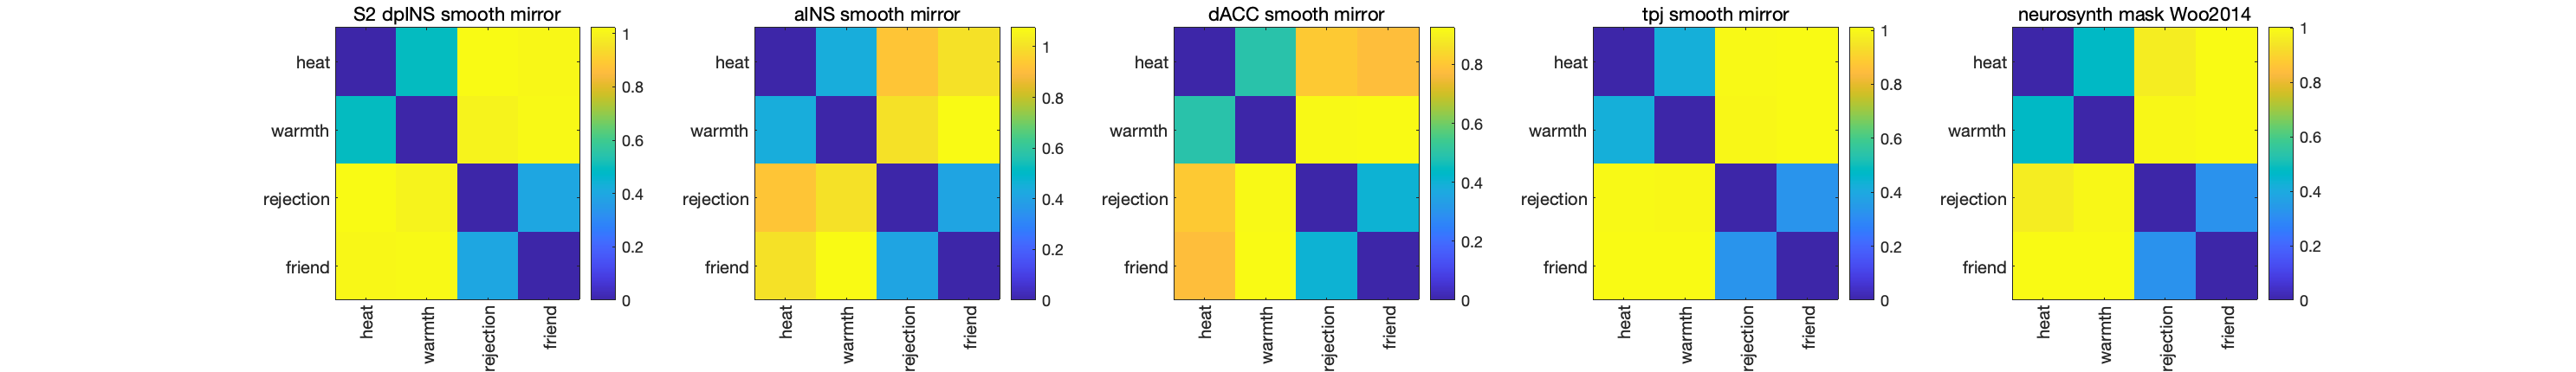

Representational Dissimilarity Matrices


figure;
set(gcf, 'position', [1         740        1487         215], 'color', 'w')
for i = 1:numel(roi)
    if i == 1, disp('Representational Dissimilarity Matrices'); end
    subplot(1,5,i);
    
    imagesc(mean(roi{i}.rdms,3));   
    colorbar;
    roi{i}.name(strfind(roi{i}.name, '_')) = ' ';
    title(roi{i}.name);
    
    set(gca, 'xticklabel', conditions, 'XTickLabelRotation', 90, ...
        'yticklabel', conditions);
end

## Step 2: Comparing brain and model RDMs

### Creating model RDMs

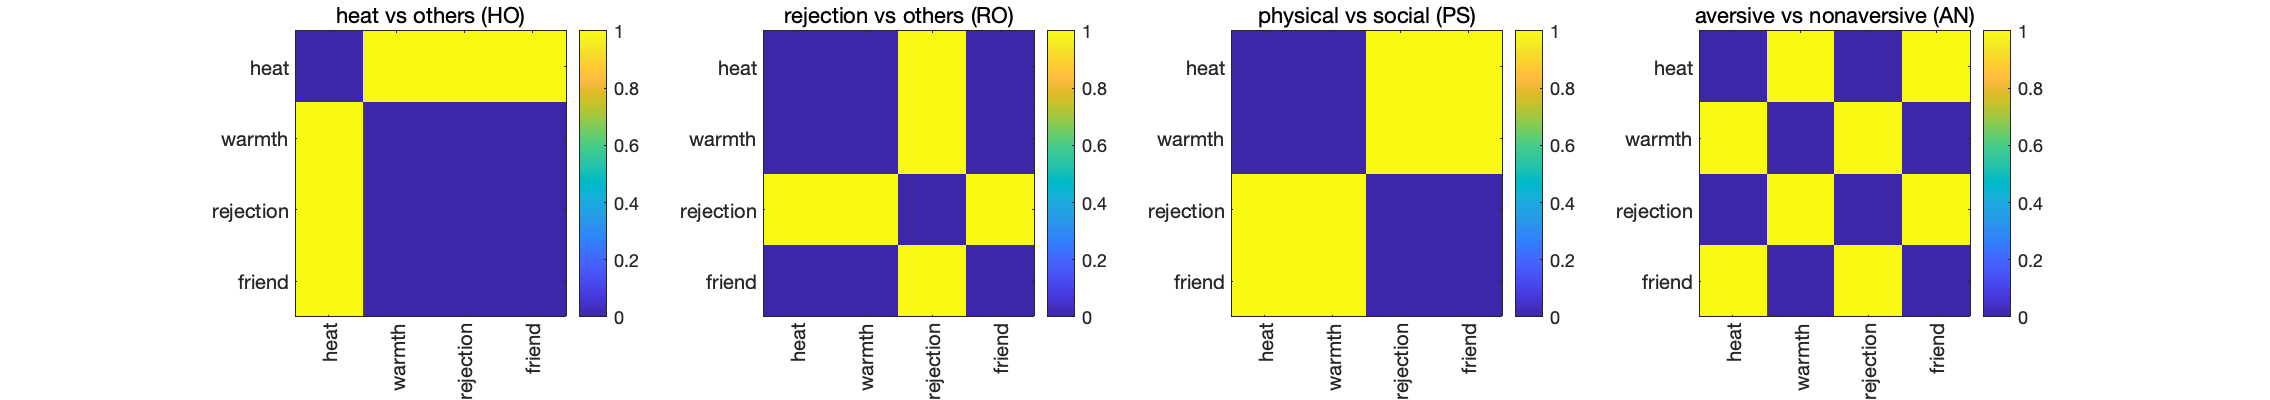

Model Representational Dissimilarity Matrices


% 1. Pain vs. others
model{1}.rdms = [0 1 1 1;1 0 0 0;1 0 0 0;1 0 0 0];
model{1}.name = 'heat vs others (HO)';

% 2. Rejection vs. others
model{2}.rdms = [0 0 1 0;0 0 1 0;1 1 0 1;0 0 1 0];
model{2}.name = 'rejection vs others (RO)';

% 3. physical vs. social
model{3}.rdms = [0 0 1 1;0 0 1 1;1 1 0 0;1 1 0 0];
model{3}.name = 'physical vs social (PS)';

% 4. aversive (pain and rejection) vs. nonaversive (warmth and friend)
model{4}.rdms = [0 1 0 1;1 0 1 0;0 1 0 1;1 0 1 0];
model{4}.name = 'aversive vs nonaversive (AN)';

figure;
set(gcf, 'position', [1         755        1135         200], 'color', 'w')

for i = 1:numel(model)
    if i == 1, disp('Model Representational Dissimilarity Matrices'); end
    subplot(1,4,i);
    imagesc(model{i}.rdms);
    colorbar;
    title(model{i}.name);
    set(gca, 'xtick', 1:4, 'ytick', 1:4);
    set(gca, 'xticklabel', conditions, 'XTickLabelRotation', 90, ...
        'yticklabel', conditions);
end

### Comparing the ROI RDMs with the model RDMs

% ROIs
for roi_i = 1:numel(roi)
    rdms.dat(:,:,roi_i) = mean(roi{roi_i}.rdms,3); % average across subjects
    rdms.names{roi_i} = roi{roi_i}.name;           % ROI names
end

% models
for model_i = 1:numel(model)
    rdms.dat(:,:,model_i+5) = model{model_i}.rdms;
    rdms.names{model_i+5} = model{model_i}.name;
end

% Preallocation
r_models = NaN(size(rdms.dat,3),size(rdms.dat,3));
upper_triang_idx = triu(true(4,4),1);

% Calculate Kendall's tau a (recommendation by Kriegeskorte)

for i = 1:size(rdms.dat,3)
    xx = squeeze(rdms.dat(:,:,i));
    for j = 1:size(rdms.dat,3)
        if i ~= j
            yy = squeeze(rdms.dat(:,:,j));
            r_models(i,j) = rankCorr_Kendall_taua(xx(upper_triang_idx), ...
                yy(upper_triang_idx));
        else
            r_models(i,j) = 1;
        end
    end
    rdms.flatten_dat(:,i) = xx(upper_triang_idx);
end


### Visualize the relationships among the regions and models using MDS (multidimensional scaling) and t-SNE

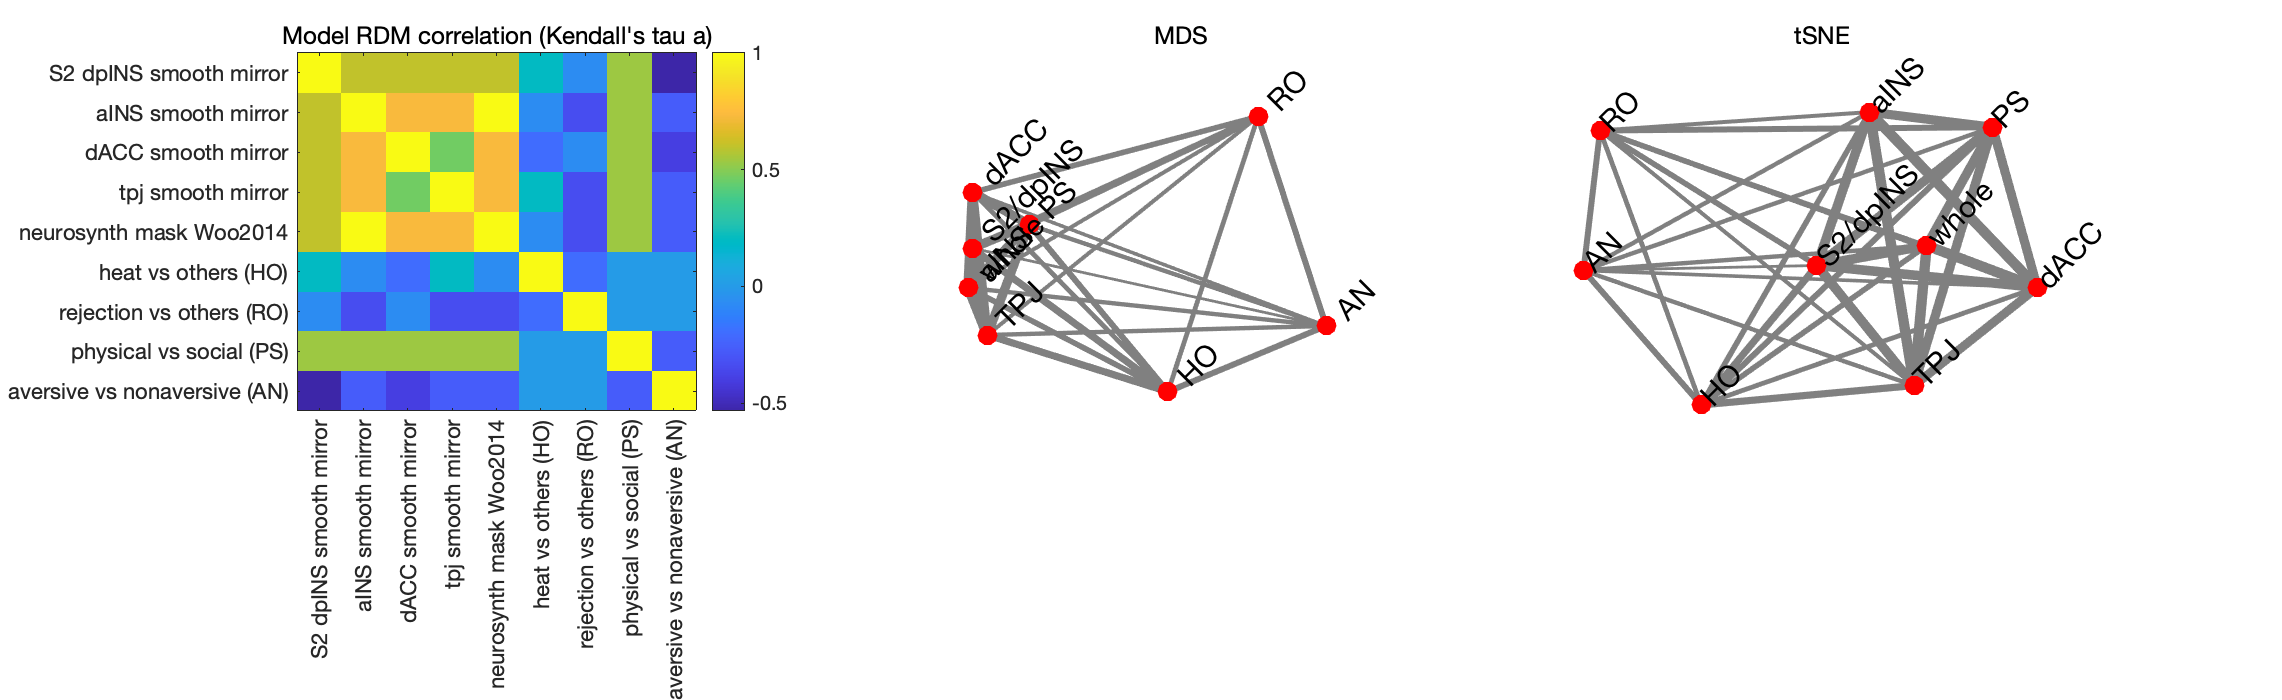

rdm_model = 1-r_models;
Y = mdscale(rdm_model,4);
figure;
set(gcf, 'position', [1         605        1141         350])
subplot(1,3,1);
imagesc(r_models);
set(gca, 'xtick', 1:9, 'ytick', 1:9, 'xticklabel', rdms.names, ...
    'XTickLabelRotation', 90, 'yticklabel', rdms.names);
colorbar;
title('Model RDM correlation (Kendall''s tau a)');

subplot(1,3,2);

for i = 1:size(Y,1)
    for j = 1:size(Y,1)
        if i ~= j
            if rdm_model(i,j) ~= 0
                h = line([Y(i,1), Y(j,1)], [Y(i,2), Y(j,2)], ...
                    'linewidth', (2-rdm_model(i,j))*3, 'color', [.5 .5 .5 .1]);
            end
        end
    end
end
hold on;
scatter(Y(:,1), Y(:,2), 100, 'r', 'filled');

short_name = {'S2/dpINS', 'aINS', 'dACC', 'TPJ', 'whole', 'HO', 'RO', 'PS', 'AN'};
text(Y(:,1)+.05, Y(:,2)+.05, short_name, 'Rotation', 45, 'fontsize', 15)
set(gca, 'xlim', [-0.5 1.3], 'ylim', [-0.6 0.9]);
axis off;
title('MDS');

subplot(1,3,3);
rng(135); % used a fixed seed (an arbitrary number) for reproducibility
Y = tsne(rdms.flatten_dat','Algorithm','exact','Distance','correlation', ...
    'Perplexity', 5);
for i = 1:size(Y,1)
    for j = 1:size(Y,1)
        if i ~= j
            if rdm_model(i,j) ~= 0
                h = line([Y(i,1), Y(j,1)], [Y(i,2), Y(j,2)], ...
                    'linewidth', (2-rdm_model(i,j))*3, 'color', [.5 .5 .5 .1]);
            end
        end
    end
end
hold on;

scatter(Y(:,1), Y(:,2), 100, 'r', 'filled');

text(Y(:,1)+10, Y(:,2)+10, short_name, 'Rotation', 45, 'fontsize', 15);
set(gca, 'xlim', get(gca, 'xlim')+[0 50], 'ylim', get(gca, 'ylim')+[0 50]);
title('tSNE')
axis off;

## Step 3: Statistical inference

Here, we will test each region with the four models above.

### Prep for bootstrap tests

% flatten the roi matrix
for roi_i = 1:numel(roi)
    roi{roi_i}.rdms_flatten = [];
    for subj_i = 1:size(roi{roi_i}.rdms,3)
        a = roi{roi_i}.rdms(:,:,subj_i);
        roi{roi_i}.rdms_flatten(:,subj_i) = a(upper_triang_idx);
    end
end
    

### Run bootstrap tests

Using bootstrap tests (resampling with replacement), we can simulate the sampling distribution 

model_names = {'HO', 'RO', 'PS', 'AN'}; % use a short model name

for roi_i = 1:numel(roi)
    clear boot_vals;
    for model_i = 1:numel(model)
        boot_rdmsmean = bootstrp(10000, @mean, roi{roi_i}.rdms_flatten')';
        for iter_i = 1:size(boot_rdmsmean,2)
            boot_vals(iter_i,1) = rankCorr_Kendall_taua(...
                model{model_i}.rdms(upper_triang_idx), ...
                boot_rdmsmean(:,iter_i));
        end
        eval(['roi{roi_i}.bootmean_' model_names{model_i} ' = mean(boot_vals);']);
        eval(['roi{roi_i}.bootste_' model_names{model_i} ' = std(boot_vals);']);
        eval(['roi{roi_i}.bootZ_' model_names{model_i} ' = roi{roi_i}.bootmean_' ...
            model_names{model_i} './roi{roi_i}.bootste_' model_names{model_i} ';']);
        eval(['roi{roi_i}.bootP_' model_names{model_i} ...
            '= 2 * (1 - normcdf(abs(roi{roi_i}.bootZ_' ...
            model_names{model_i} ')));']);
        eval(['roi{roi_i}.ci95_' model_names{model_i} ...
            ' = [prctile(boot_vals, 2.5); prctile(boot_vals, 97.5)];']);
    end
    
    roi{roi_i}.noise_ceiling(1,1) = mean(corr(mean(roi{roi_i}.rdms_flatten,2), ...
        roi{roi_i}.rdms_flatten));

    for ii = 1:size(roi{roi_i}.rdms_flatten,2)
        temp = roi{roi_i}.rdms_flatten;
        temp(:,ii) = [];
        lower_bound_i(ii,1) = corr(mean(temp,2), roi{roi_i}.rdms_flatten(:,ii));
    end
    
    roi{roi_i}.noise_ceiling(1,2) = mean(lower_bound_i);
end

### Plot the results

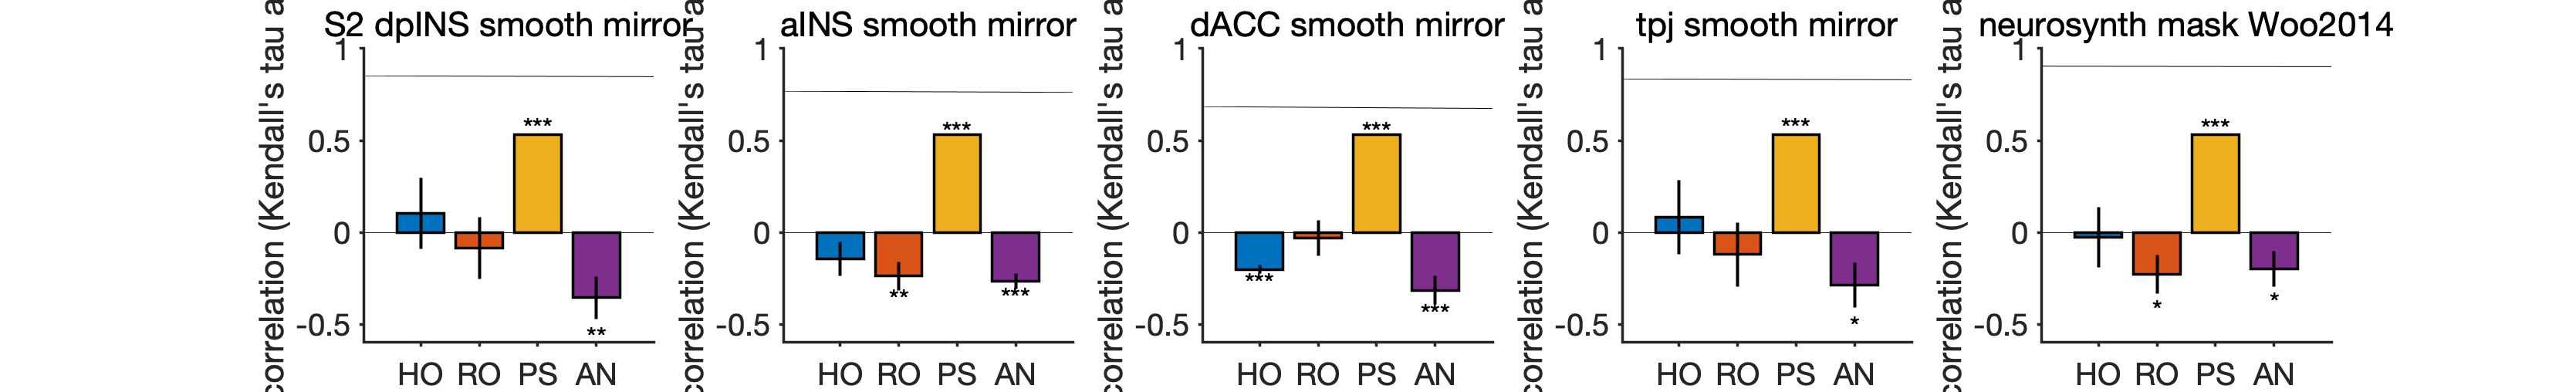

figure;
set(gcf, 'position', [1         701        1669         254]);
for roi_i = 1:numel(roi)
    y = [roi{roi_i}.bootmean_HO roi{roi_i}.bootmean_RO roi{roi_i}.bootmean_PS ...
        roi{roi_i}.bootmean_AN];
    e = [roi{roi_i}.bootste_HO roi{roi_i}.bootste_RO roi{roi_i}.bootste_PS ...
        roi{roi_i}.bootste_AN];
    p = [roi{roi_i}.bootP_HO roi{roi_i}.bootP_RO roi{roi_i}.bootP_PS ...
        roi{roi_i}.bootP_AN];
    subplot(1, numel(roi), roi_i);
    bar_wani_2016(y, e, .8, 'errbar_width', 0, 'ast', p, 'use_samefig', ...
        'ylim', [-.6 1]);
    patch(get(gca, 'xlim'), roi{roi_i}.noise_ceiling, [.7 .7 .7]);
    title(roi{roi_i}.name);
    ylabel('correlation (Kendall''s tau a)');
    xticklabels(model_names);
end

## Conclusion

The representational similarity patterns of our data support the physical vs. social model (modality specificity model) the best. We might want to do further analyses, e.g., 1) pair-wise comparisons between the model fit (e.g., HO vs. RO; e.g., in dACC, RO > HO and in whole-brain. HO > RO), 2) searchlight analysis (= doing this for all the regions), and 3) GLM based approach (e.g., HO controlling for PS). 